# **Reaction Engineering Report Matlab Code Group 17 **

**Barbacci Schettino, Marco**

**Choithani, Shaurya**

**Sarker, Abid**

**Tewinpagti, Bam**

**Weston, Chris**

Task 1: 

For the first task we deived material balances along side a unit analysis

Mass Balances

The derivation begins with a general mass balance equation at steady state represented as:

input - output - consumption = 0


$${\left.{\left(M\right.}_A \cdot n_A \right)}_v -\;{\left.{\left(M\right.}_A \cdot n_A \right)}_{v+\Delta v} -\;M_a \cdot r_A \Delta \;V_{R\;} =\;0$$


Dividing by $M_A$ and taking the limit as ${\Delta V}_R$ approaches 0 and rearranging gives:


$$\frac{{\textrm{dn}}_A }{{\textrm{dV}}_R }-r_A =0,{\;\;\;\;r}_A =-\frac{{\textrm{dn}}_A }{{\textrm{dV}}_R }$$


Multiplying by crossectional area, catalyst density and (1- bedvoidage) to obtain the derivative with respect to length and ensuring consitency of units on both sides 


$$r_A \cdot A\cdot \rho_c \cdot \left(1-\varepsilon \right)=-\frac{{\textrm{dn}}_A }{{\textrm{dV}}_R }$$


close all
clear
clc

In this section we set global variables that are unchanged throughout the reactor system. This allows us to reduce the lines of code, make the code well structured and reduce errors when writing code

%defining global variables
global gc;
%initial conditions global variables
gc.molc=[0.26281112 0.105124448 0.018559258 1.70E-06 1.28E-06 0.613505174 0 0 ]; %inlet mol compositon 
gc.Mr=[28 32 44 99 62.5 28 44 18]; %molecular weight
gc.tmolMr=sum(gc.Mr.*gc.molc);%part of the calculation to deterine mole flow per second
gc.m_T=0.03*1000; % overall inlet mass flowrate converted to seconds Kg/s
gc.n0T=(gc.m_T)./gc.tmolMr;%intial molar flowrates of reacting species
gc.n0Tsum=sum(gc.n0T); %total molar flowrate in mol/s
%reactor globa;l variables
gc.T0=220+273.15; %K
gc.Rg=8.314;% gas constant in j/(mol K)
gc.Pg=2.1*10^6; % inlet pressure in Pa
gc.D = 0.05; % diameter of reactor, m
gc.A = (pi*(gc.D)^2)/4; % cross-sectional area of reactor, m^2
%catalyst global cariables
gc.Void_frac = 0.4; % bed voidage
gc.rho_cat = 1500; %catalyst partical density Kg/(m^3)
gc.D_cat = 0.0055; %diameter of catalyst, m
gc.L_cat = 0.0016; %catalyst partical cylinder length (m)
gc.D_p=7.04*10^-3;%equivalent partical diameter (m)
%Reaction kinetics global variabls
gc.Ea1 = [-4.5036 0.88555 0.34102 0.89970 -13.770 -33.642 1.1471 4.5178]; %these are the reaction constant values set in an array making coding shorter and easier to call
gc.Ea2 = [-7.4464*10^4 -9.6484*10^4 -8.5726*10^4 -1.1556*10^5 -2.1059*10^4 9.4655*10^4 -1.0397*10^5 -2.4215*10^4];% also reaction constants 
%global Values for heat capacity
gc.a=[-6.3879 29.659 24.9974 0 0 26.092 -23.258 30.092];%Cp constant a in an array for different compounds
gc.b=[184.4019 6.1373 55.187 0 0 8.2188 275.6997 6.8325]./1000;%Cp constant b in an array for different compounds
gc.c=[-112.972 -1.1865 -33.6914 0 0 -1.9761 -188.973 6.7934]./1000^2;%Cp constant c in an array for different compounds
gc.d=[28.49593 0.09578 7.94839 0 0 0.15927 51.0335 -2.53448]./1000^3;%Cp constant d in an array for different compounds
gc.e=[0.31554 -0.21966 -0.13664 0 0 0.044434 0.38693 0.082139]./1000^(-2);%Cp constant e in an array for different compounds


Task 2:

For this section we consider just the material balances for an isobaric and isothermal reactor system and develop a functioniing matlab code using ODE15 solver to solve the material balances odes derived from Task 1.

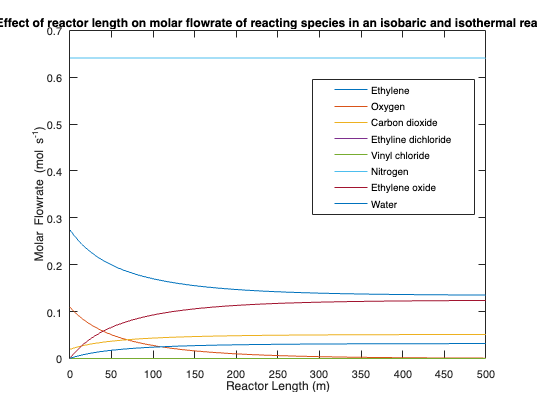

%Setting linspace for reactor length
zrange=linspace(0,500,1000);
%finding the inital molar flowrate for each compound
n01=gc.n0T.*gc.molc;
% setting the inital conditions for the function
IC=[n01(1) n01(2) n01(3) n01(4) n01(5) n01(6) n01(7) n01(8) gc.Pg gc.T0];
% Solving the ODEs
[z1, mol1] = system_ode1(zrange,IC,true,true);
% Plot for molar flowrates of every species along the reactor length
F1 = figure(1);
plot(z1,real(mol1(:,1)))
hold on
plot(z1,real(mol1(:,2)))
plot(z1,real(mol1(:,3)))
plot(z1,real(mol1(:,4)))
plot(z1,real(mol1(:,5)))
plot(z1,real(mol1(:,6)))
plot(z1,real(mol1(:,7)))
plot(z1,real(mol1(:,8)))
legend('Ethylene','Oxygen','Carbon dioxide','Ethyline dichloride','Vinyl chloride','Nitrogen','Ethylene oxide','Water')
xlabel('Reactor Length (m)')
ylabel('Molar Flowrate (mol s^{-1})')
title('Effect of reactor length on molar flowrate of reacting species in an isobaric and isothermal reactor')
hold off
legend("Position", [0.58384,0.47055,0.2987,0.33045])

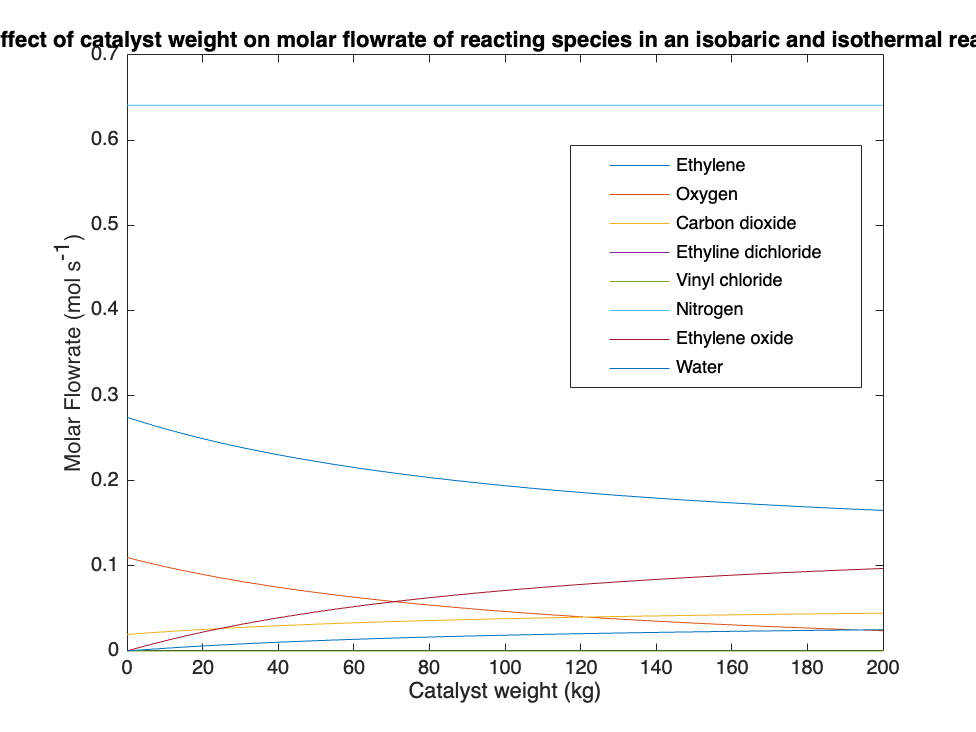


%ploting molar flowrate over catalyst weight
catalystweight=gc.rho_cat*(1-gc.Void_frac)*gc.A.*z1;%finding catalyst weight across reactor length
F2 = figure(2);
plot(catalystweight,real(mol1(:,1)))
hold on
plot(catalystweight,real(mol1(:,2)))
plot(catalystweight,real(mol1(:,3)))
plot(catalystweight,real(mol1(:,4)))
plot(catalystweight,real(mol1(:,5)))
plot(catalystweight,real(mol1(:,6)))
plot(catalystweight,real(mol1(:,7)))
plot(catalystweight,real(mol1(:,8)))
xlim([0 200])
legend('Ethylene','Oxygen','Carbon dioxide','Ethyline dichloride','Vinyl chloride','Nitrogen','Ethylene oxide','Water')
xlabel('Catalyst weight (kg)')
ylabel('Molar Flowrate (mol s^{-1})')
title('Effect of catalyst weight on molar flowrate of reacting species in an isobaric and isothermal reactor')
hold off
legend("Position", [0.58384,0.47055,0.2987,0.33045])

Task 3:

In this section we consider pressure drop, which is done by adding a pressure drop ODE in the fucntion and adding if statments so the conditions can be called out.

The pressure drop equation is as follows:


$$\frac{\textrm{dP}}{\textrm{dz}}=-\frac{1\ldotp 75\cdot G^2 \cdot \left(1-\varepsilon \right)}{D_p \cdot \rho \cdot \varepsilon }$$


zrange=linspace(0,100,1000);%setting linspace for the reactor length
%calling the function for non-isobaric and isothermal conditions and plotting the pressure drop
[z1, mol1] = system_ode1(zrange, IC, false,true);

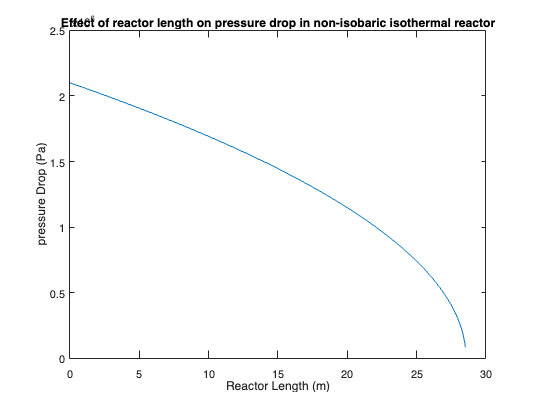

F3 = figure(3);
plot(z1,mol1(:,9))
xlabel('Reactor Length (m)')
ylabel('pressure Drop (Pa)')
title('Effect of reactor length on pressure drop in non-isobaric isothermal reactor')
hold off

Task 4:

In this section we consider the energy balacnes for a non isothermal reactor where the following ODE is derived from energy balance equation particullarly making sure that the units coincide with the intended units.


$$\frac{\textrm{dT}}{{\textrm{dV}}_R }=-\frac{\rho_c \cdot \left(1-\varepsilon \right)\sum_i \left.{\left(H\right.}_{f,i} \cdot r_i \right)}{\sum_i n_i {\cdot C}_{p,i} }$$


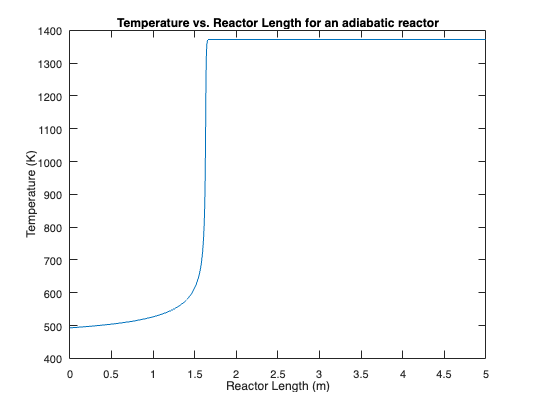

%temperature vs reactor length plot
zrange=linspace(0,5,10000);%setting a linspace for a range of reactor lengths and increasing step intervals to smooth the curves
%calling the function for non-isobaric and non-isothermal case
[z1, mol1] = system_ode1(zrange, IC, false,false);
F4 = figure(4);
plot(z1,real(mol1(:,10)))
xlim([0 5])
xlabel('Reactor Length (m)')
ylabel('Temperature (K)')
title('Temperature vs. Reactor Length for an adiabatic reactor')
hold off

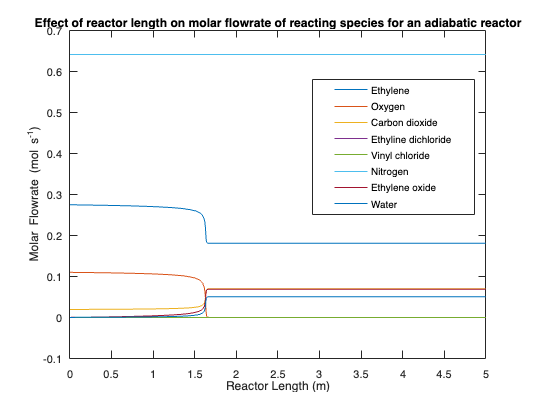


%ploting molar flowrates over reactor length for the non-isobaric and non-isothermal case
F5 = figure(5);
plot(z1,real(mol1(:,1)))
hold on
plot(z1,real(mol1(:,2)))
plot(z1,real(mol1(:,3)))
plot(z1,real(mol1(:,4)))
plot(z1,real(mol1(:,5)))
plot(z1,real(mol1(:,6)))
plot(z1,real(mol1(:,7)))
plot(z1,real(mol1(:,8)))
hold off
legend('Ethylene','Oxygen','Carbon dioxide','Ethyline dichloride','Vinyl chloride','Nitrogen','Ethylene oxide','Water')
xlabel('Reactor Length (m)')
ylabel('Molar Flowrate (mol s^{-1})')
title('Effect of reactor length on molar flowrate of reacting species for an adiabatic reactor')
legend("Position", [0.58384,0.47055,0.2987,0.33045])

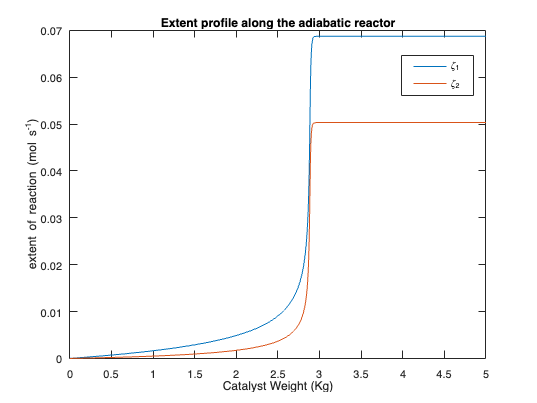

%plot for rate of reaction 1 and 2 against temperature 
F6 = figure(6);
catalystweight=gc.rho_cat*(1-gc.Void_frac)*gc.A.*z1;%getting catalys weight over the length range
plot(catalystweight,real(mol1(:,7)-n01(7)))
hold on
plot(catalystweight,real(mol1(:,8)-n01(8)))
hold off
xlim([0 5])
legend('\zeta_1', '\zeta_2')
xlabel('Catalyst Weight (Kg)')
ylabel('extent of reaction (mol s^{-1})')
title('Extent profile along the adiabatic reactor') 
legend("Position", [0.748,0.76467,0.13247,0.098616])

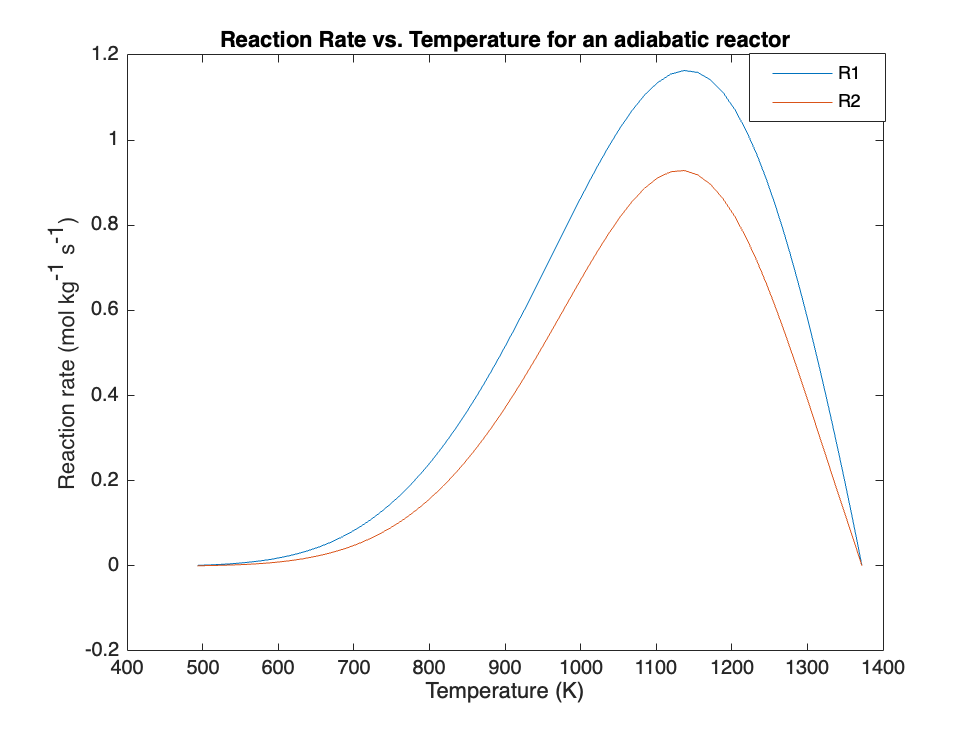

%taking all the output values for non isobaric and non-isothermal reactor
T=mol1(:,10);
P0=mol1(:,9);
n_C2H4=mol1(:,1);
n_O2=mol1(:,2);
n_CO2=mol1(:,3);
n_C2H4O=mol1(:,7);
n_H20=mol1(:,8);
%calling all the initial conditions 
n0_C2H4=IC(1);
n0_O2=IC(2);
n0_CO2=IC(3);
n0_inh=IC(4);
n0_VC=IC(5);
n0_N2=IC(6);
n0_C2H4O=IC(7);
n0_H20=IC(8);

%material balances
n0_T=n0_C2H4+n0_O2+n0_CO2+n0_VC+n0_inh+n0_N2+n0_C2H4O+n0_H20;
n_Tsum=n_C2H4+ n_O2+ n_CO2+ n0_VC+ n0_inh+ n0_N2+ n_C2H4O+ n_H20;

% mole fractions
y1=n_C2H4./n_Tsum;
y2=n_O2./n_Tsum;
y3=n_CO2./n_Tsum;
y4=n0_inh./n_Tsum;
y5=n0_VC./n_Tsum;
y6=n0_N2./n_Tsum;
y7=n_C2H4O./n_Tsum;
y8=n_H20./n_Tsum;

% compound partial pressures
p1=y1.*P0;
p2=y2.*P0;
p3=y3.*P0;
p4=y4.*P0;
p5=y5.*P0;
p6=y6.*P0;
p7=y7.*P0;
p8=y8.*P0;

K = exp(gc.Ea1+(gc.Ea2./(gc.Rg.*T)));%rate constants calulations

%reaction rate equations in mol/(Kg s)
R1=(1/3600).*(K(:,1).*p1.*p2)./(1+K(:,3).*p2.^(1/2)+K(:,4).*p2+K(:,5).*p1.*p2.^(1/2)+K(:,6).*p3+K(:,7).*p8+K(:,8).*p4./p5);
R2=(1/3600).*(K(:,2).*p1.*p2)./((1+K(:,3).*p2.^(1/2)+K(:,4).*p2+K(:,5).*p1.*p2.^(1/2)+K(:,6).*p3+K(:,7).*p8+K(:,8).*p4./p5).^2);%

%plotting the reaction rates over temperature for a non-isobaric and non-isothermal reactor
figure;
plot(real(mol1(:,10)),real(R1));
hold on 
plot(real(mol1(:,10)),real(R2));

xlabel('Temperature (K)')
ylabel('Reaction rate (mol kg^{-1} s^{-1})');
title('Reaction Rate vs. Temperature for an adiabatic reactor')
legend('R1', 'R2')
legend("Position", [0.76792,0.83363,0.13766,0.091696])
hold off

Task 5 a)

In this section we will first select the optimal conversion of oxygen for interstage cooling. This was done by setting a for loop for the different oxygen conversions and within the while loop making a fore loop to simulate the interstage cooling. We then plotted graphs that considered the total length and amounts of reactor tube required to reach a output of 100 tonnes of ethlyene oxide per day. Thus we were then able to do a cost analysis to consider the optimal conversion of oxygen.

cx=(0.05:0.05:0.95);%conversion values we are testing for 
target=100e+06/(44*3600*24);
%setting empty arrays to store the data for the for and while loop
n_cooler = double.empty(length(cx),0);
n_z = double.empty(length(cx),0);
nparallel=double.empty(length(cx),0);
Cooler_Duty= double.empty(length(cx),0);
zrange=linspace(0,10,10000);
duty=double.empty(length(cx),0);
ztotal=double.empty(length(cx),0);
%heat capactiy calculations
Cp= (gc.a + gc.b.*T + gc.c.*T.^2 + gc.d.*T.^3 + gc.e.*T.^(-2));
%output relevant Cp values
Cp_C2H4= @(T) Cp(1);
Cp_O2= @(T) Cp(2);
Cp_CO2= @(T) Cp(3);
Cp_N2= @(T) Cp(6);
Cp_C2H4O= @(T) Cp(7);
Cp_H20= @(T) Cp(8);
%total heat capacity

%the following code is to simulate the interstage cooling
% Explanation: The interstage cooling is implemented when the reactor temperature is achieved at MAWT before the conversion of ethene is in 0.8
% if the conversion of ethene is achieved the while loop ends
for xindedx = 1:length(cx)
    x_target = cx(xindedx); % Target conversion for this iteration
    %setting inital conditions and constants 
    x_current = 0;
    x = 0.0;
    Tlim = 600; 
    z = 0;
    mol = [0,0,0,0,0,0,0,0,0,0];
    count = 0;
    Tcool = 50;
    IC =[n01(1) n01(2) n01(3) n01(4) n01(5) n01(6) n01(7) n01(8) gc.Pg gc.T0];
    zrange=linspace(0,10,10000);
   while x < x_target % condition for loop to be running until the conversion is reached to 0.8
      [z1, mol1] = system_ode1(zrange, IC, false, false);
      j = max(find((mol1(:,10) < Tlim))); % find an index of an array that temperature is just below MAWT
      k = min(find(1-mol1(:,2)/n01(2) > x_target)); % find an index of an array that molar flowrate is just above 0.8 conversion
        
    
        if k < j % when 0.8 conversion is achieved before the temperature goes above MAWT, then we can stop the loop by calculating the conversion(x)
            z = [z ; (z1(1:k) + z(length(z),1))];%length of the reactor
            n_z=[n_z ; z(length(z),1)];%number of reactors
            mol = [mol ; mol1(1:k,:)];%mole flows at comversion
            x = 1 - mol1(k,2)/n01(2);% calculated conversion
            parallel = ceil(target/(mol1(k,7)));%calculating the multiplier of reactor tube needed to reach ethylene oxide production
            nparallel = [nparallel;parallel];%soting for each iteration
            n_cooler = [n_cooler; count];%number of coolers
            fprintf('Acheived x = %.2f with %4.2f number of interstage coolers, %8.3f total length of all reactors and %12.3f decrease in temperature by cooler',x, count, z(length(z),1), Tcool)
            fprintf("\n")

        else % when temperature goes above MAWT before 0.8 conversion is achieved, then we decrease the reactor temperature by 50K and put it into a new reactor
            x = 1 - mol1(j,2)/n01(2);%conversion calculation at tlim
            z = [z ; (z1(1:j) + z(length(z),1))];%length of reactor    
            mol = [mol ; mol1(1:j,:)];%mol flows at Tlim
            IC = [mol1(j,1:9),mol1(j,10) - Tcool];%new intial condition at tlim to do interstage cooling
            count = count + 1;%count of number of iterations of the while loop
            %calculating the duty per compound
            Q_C2H4= integral(Cp_C2H4,Tlim-Tcool,Tlim,"ArrayValued",true);
            Q_O2= integral(Cp_O2,Tlim-Tcool,Tlim,"ArrayValued",true);
            Q_CO2= integral(Cp_CO2,Tlim-Tcool,Tlim,"ArrayValued",true);
            Q_N2= integral(Cp_N2,Tlim-Tcool,Tlim,"ArrayValued",true);
            Q_C2H4O= integral(Cp_C2H4O,Tlim-Tcool,Tlim,"ArrayValued",true);
            Q_H20= integral(Cp_H20,Tlim-Tcool,Tlim,"ArrayValued",true);
            Q_array=[Q_C2H4 Q_O2 Q_CO2 Q_N2 Q_C2H4O Q_H20];%placing the dutys in an array to simplify calculations
            n_h=[mol1(j,1) mol1(j,2) mol1(j,3) mol1(j,6) mol1(j,7) mol1(j,8)]; %molar flows for relevant Cp total calulations
            n0_inh=IC(4);
            n0_VC=IC(5);
            n_hsum=sum(n_h)+n0_inh+n0_VC; %sum of molar flows
            y=n_h./n_hsum;%finding the compositions at Tlim
            duty(count)= sum(y.*Q_array)/1000;% calculating the duty of each interstage cooling in kW
        end
   end
   fprintf("1 conv achieved")
end

Acheived x = 0.05 with 0.00 number of interstage coolers,    1.173 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.10 with 0.00 number of interstage coolers,    1.442 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.15 with 1.00 number of interstage coolers,    1.666 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.20 with 2.00 number of interstage coolers,    1.897 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.25 with 3.00 number of interstage coolers,    2.134 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.30 with 4.00 number of interstage coolers,    2.380 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.35 with 5.00 number of interstage coolers,    2.636 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.40 with 6.00 number of interstage coolers,    2.903 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.45 with 7.00 number of interstage coolers,    3.183 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.50 with 8.00 number of interstage coolers,    3.478 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.55 with 9.00 number of interstage coolers,    3.792 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.60 with 10.00 number of interstage coolers,    4.132 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.65 with 11.00 number of interstage coolers,    4.501 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.70 with 12.00 number of interstage coolers,    4.911 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.75 with 13.00 number of interstage coolers,    5.377 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.80 with 14.00 number of interstage coolers,    5.917 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.85 with 15.00 number of interstage coolers,    6.576 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.90 with 17.00 number of interstage coolers,    7.453 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

Acheived x = 0.95 with 18.00 number of interstage coolers,    8.943 total length of all reactors and       50.000 decrease in temperature by cooler

1 conv achieved

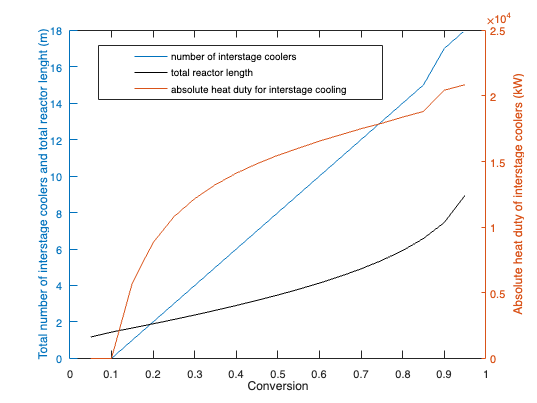



dutysum=double.empty(length(cx),0);
tot_duty=double.empty(length(cx),0);
%For loop to calulate toal cooler duty per conversion
    for i=1:length(cx)
        dutysum(i)= sum(duty(1:n_cooler(i,:)));%calculating the total duty for one reactor tube
        tot_duty(i)=nparallel(i).*dutysum(i);%finding also the duty required to cool the full reactor stream
    end
ztotal=n_z;%total reactor length
ztotalcost= n_z.*19; %capex for one reactor tube in pound
zavg=(n_z/(n_cooler+1));%average reactor tube length
n_coolert = (n_cooler);
n_reactort = nparallel.*((n_cooler)+1);
Reactorcost=14000+15400.*(gc.A.*nparallel.*ztotal).^0.7;%calulating total capex for the reactor
duty_cost=tot_duty.*0.1;%$per Kw

%cost analysis plots
figure
yyaxis left
plot(transpose(cx),n_coolert)
hold on
plot(transpose(cx),ztotal,'K-')
hold on
xlabel("Conversion");
ylabel("Total number of interstage coolers and total reactor lenght (m)")
yyaxis right
plot(transpose(cx),tot_duty);
legend('number of interstage coolers', 'total reactor length','absolute heat duty for interstage cooling')
hold off
ylabel("Absolute heat duty of interstage coolers (kW)")
legend("Position", [0.18656,0.75476,0.52208,0.13149])

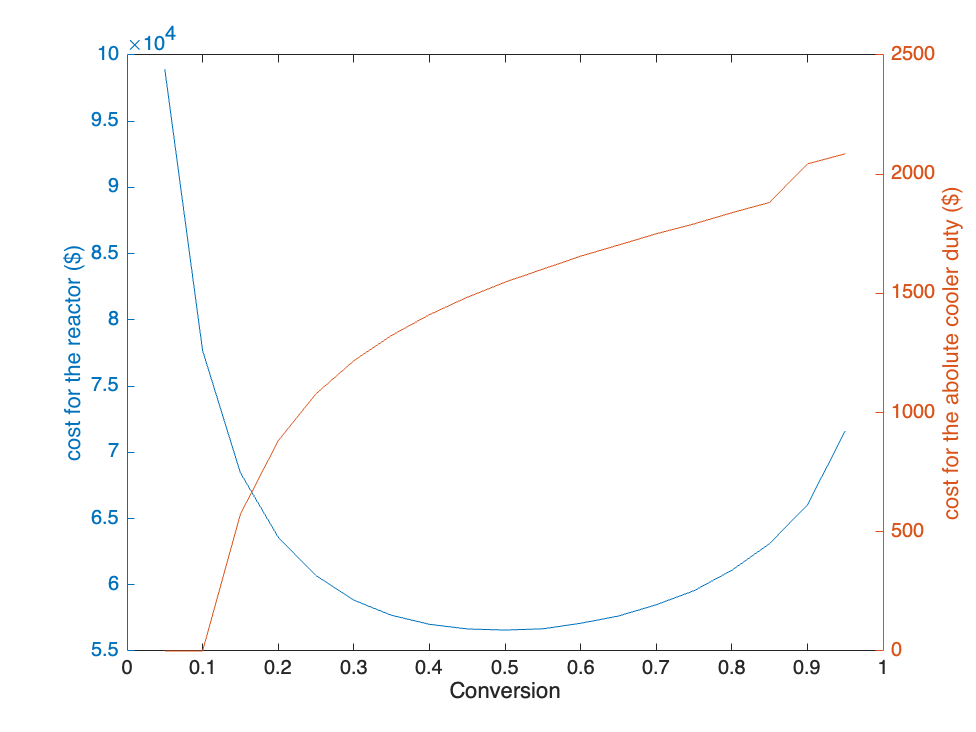


figure;
yyaxis left
plot(transpose(cx),Reactorcost)
hold on
xlabel("Conversion")
ylabel("cost for the reactor ($)")
yyaxis right
plot(transpose(cx),duty_cost)
hold off
ylabel("cost for the abolute cooler duty ($)")

Task 5 b) 

Interstage cooling with appropriate conversion (0.8)

%setting inital conditions for while loops 
zrange=linspace(0,10,10000);
x = 0.0;
Tlim = 600; 
z = 0;
mol = [0,0,0,0,0,0,0,0,0,0];
count = 0;
Tcool = 50;
Cooler_Duty=0;
conv=0.85;
IC =[n01(1) n01(2) n01(3) n01(4) n01(5) n01(6) n01(7) n01(8) gc.Pg gc.T0];

%heat capactiy calculations
Cp= (gc.a + gc.b.*T + gc.c.*T.^2 + gc.d.*T.^3 + gc.e.*T.^(-2));
%output relevant Cp values
Cp_C2H4= @(T) Cp(1);
Cp_O2= @(T) Cp(2);
Cp_CO2= @(T) Cp(3);
Cp_N2= @(T) Cp(6);
Cp_C2H4O= @(T) Cp(7);
Cp_H20= @(T) Cp(8);
%total heat capacity

%Implementation of Interstage Cooling
% Explanation: The interstage cooling is implemented when the reactor
% temperature is achieved at MAWT before the conversion of ethene is in 0.8
% Once the conversion of ethene is achieved the whole loop ends

while x < conv % condition for loop to be running until the conversion is reached to 0.8
    [z1, mol1] = system_ode1(zrange, IC, false, false);
    j = max(find((mol1(:,10) < Tlim))); % find an index of an array that temperature is just below MAWT
    k = min(find(1-mol1(:,2)/n01(2) > conv)); % find an index of an array that molar flowrate is just above 0.8 conversion
    
    
    if k < j % when 0.8 conversion is achieved before the temperature goes above MAWT, then we can stop the loop by calculating the conversion(x)
        z = [z ; (z1(1:k) + z(length(z),1))];    
        mol = [mol ; mol1(1:k,:)];
        x = 1 - mol1(k,2)/n01(2);
        fprintf('Acheived x = %.2f with %4.2f number of interstage coolers, %8.3f total length of all reactors and %12.3f decrease in temperature by cooler', x, count, z(length(z),1), Tcool)
        fprintf("\n")

    else % when temperature goes above MAWT before 0.8 conversion is achieved, then we decrease the reactor temperature by 50K and put it into a new reactor
        x = 1 - mol1(j,2)/n01(2);
        z = [z ; (z1(1:j) + z(length(z),1))];    
        mol = [mol ; mol1(1:j,:)];
        IC = [mol1(j,1:9),mol1(j,10) - Tcool];
        count = count + 1;
        Q_C2H4= -integral(Cp_C2H4,Tlim-Tcool,Tlim,"ArrayValued",true);
        Q_O2= -integral(Cp_O2,Tlim-Tcool,Tlim,"ArrayValued",true);
        Q_CO2= -integral(Cp_CO2,Tlim-Tcool,Tlim,"ArrayValued",true);
        Q_N2= -integral(Cp_N2,Tlim-Tcool,Tlim,"ArrayValued",true);
        Q_C2H4O= -integral(Cp_C2H4O,Tlim-Tcool,Tlim,"ArrayValued",true);
        Q_H20= -integral(Cp_H20,Tlim-Tcool,Tlim,"ArrayValued",true);
        Q_array=[Q_C2H4 Q_O2 Q_CO2 Q_N2 Q_C2H4O Q_H20];
        n_h=[mol1(j,1) mol1(j,2) mol1(j,3) mol1(j,6) mol1(j,7) mol1(j,8)];
        n0_inh=IC(4);
        n0_VC=IC(5);
        n_hsum=sum(n_h)+n0_inh+n0_VC;
        y=n_h./n_hsum;
        Cooler_Duty= Cooler_Duty + sum(y.*Q_array)/1000;
    end
end

Acheived x = 0.85 with 15.00 number of interstage coolers,    6.576 total length of all reactors and       50.000 decrease in temperature by cooler

%maybe add line to show accumulated cooler duty
% plot the outcome

figure; 
yyaxis left
plot(z(2:end),mol(2:end,10))
hold on
coolerDutyText = sprintf('Cooler duty = %.2f kW', Cooler_Duty);
text(1.3, 540, coolerDutyText, 'FontSize', 9)
legend('Interstage cooling','O_2 conversion')

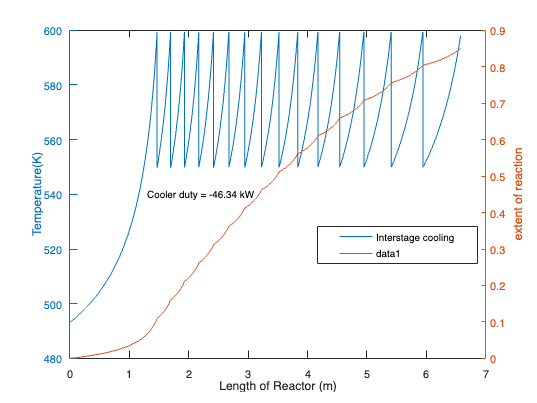

ylabel('Temperature(K)')
xlabel('Length of Reactor (m)')
yyaxis right
plot(z(2:end),(1 - (mol(2:end,2)./n01(2))));
hold off
ylabel('extent of reaction')
legend("Position", [0.59251,0.34638,0.29351,0.091696])

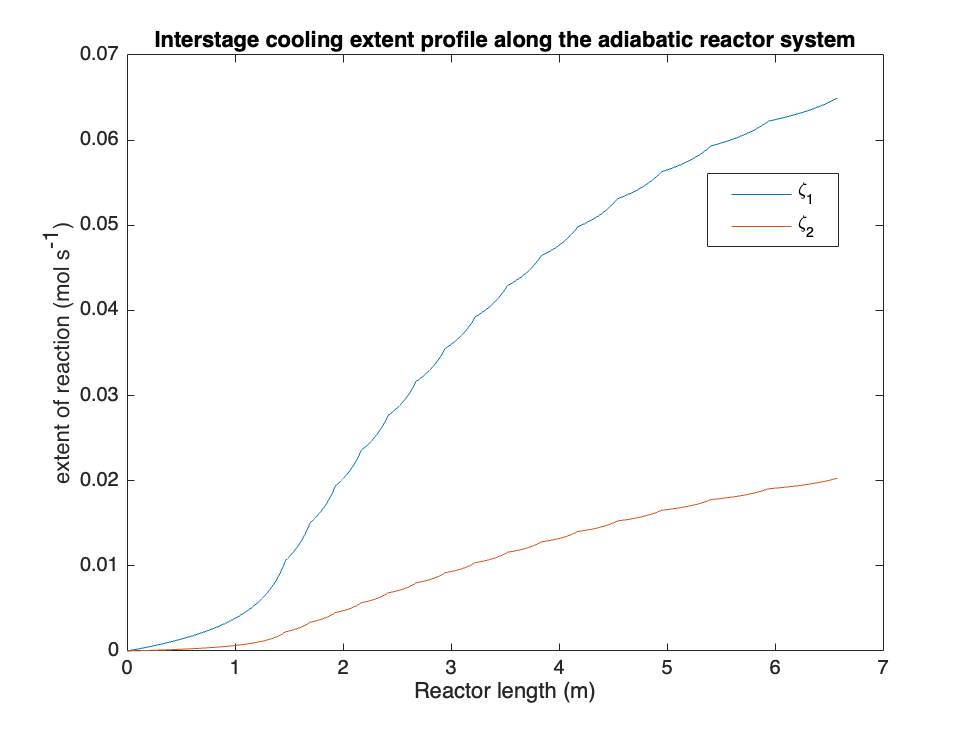


figure;
plot(z(2:end),mol(2:end,7)-mol(2,7))
hold on
plot(z(2:end),(mol(2:end,8)-mol(2,8))/2)
legend('\zeta_1', '\zeta_2')
xlabel('Reactor length (m)')
ylabel('extent of reaction (mol s^{-1})')
title('Interstage cooling extent profile along the adiabatic reactor system')
hold off 
legend("Position", [0.72561,0.66323,0.13247,0.098616])

Sensitivity analysis: 

This section will cover the sensitivity analysis for change in temperature drop 

n01=gc.n0T.*gc.molc;
IC =[n01(1) n01(2) n01(3) n01(4) n01(5) n01(6) n01(7) n01(8) gc.Pg gc.T0];
[z1, mol1] = system_ode1(zrange, IC, false, false);
T=mol1(:,10);
Tcool=(20:10:70);
target=100e+06/(44*3600*24);
n_cooler = double.empty(length(Tcool),0);
n_z = double.empty(length(Tcool),0);
nparallel=double.empty(length(Tcool),0);
Cooler_Duty= double.empty(length(Tcool),0);
zrange=linspace(0,10,10000);
duty=double.empty(length(Tcool),0);
ztotal=double.empty(length(Tcool),0);
%heat capactiy calculations
Cp= (gc.a + gc.b.*T + gc.c.*T.^2 + gc.d.*T.^3 + gc.e.*T.^(-2));
%output relevant Cp values
Cp_C2H4= @(T) Cp(1);
Cp_O2= @(T) Cp(2);
Cp_CO2= @(T) Cp(3);
Cp_N2= @(T) Cp(6);
Cp_C2H4O= @(T) Cp(7);
Cp_H20= @(T) Cp(8);
%total heat capacity

%Implementation of Interstage Cooling
% Explanation: The interstage cooling is implemented when the reactor
% temperature is achieved at MAWT before the conversion of ethene is in 0.8
% Once the conversion of ethene is achieved the whole loop ends
   for i = 1:length(Tcool)
   
    
   % Target conversion for this iteration
   x_current = 0;
   x = 0.0;
   Tlim = 600; 
   z = 0;
   mol = [0,0,0,0,0,0,0,0,0,0];
   count = 0;
   Cooler_Duty=0;
   IC =[n01(1) n01(2) n01(3) n01(4) n01(5) n01(6) n01(7) n01(8) gc.Pg gc.T0]; 
    zrange=linspace(0,10,10000);
        while x < 0.85 % condition for loop to be running until the conversion is reached to 0.8
        [z1, mol1] = system_ode1(zrange, IC, false, false);
        j = max(find((mol1(:,10) < Tlim))); % find an index of an array that temperature is just below MAWT
        k = min(find(1-mol1(:,2)/n01(2) > 0.85)); % find an index of an array that molar flowrate is just above 0.8 conversion
    
    
            if k < j % when 0.8 conversion is achieved before the temperature goes above MAWT, then we can stop the loop by calculating the conversion(x)
            z = [z ; (z1(1:k) + z(length(z),1))];
            n_z=[n_z ; z(length(z),1)];
            mol = [mol ; mol1(1:k,:)];
            x = 1 - mol1(k,2)/n01(2);
            parallel = ceil(target/(mol1(k,7))); 
            nparallel = [nparallel;parallel];
            n_cooler = [n_cooler; count];
            fprintf('Acheived x = %.2f with %4.2f number of interstage coolers, %8.3f total length of all reactors and %12.3f decrease in temperature by cooler',x, count, z(length(z),1), Tcool)
            fprintf("\n")
    
            else % when temperature goes above MAWT before 0.8 conversion is achieved, then we decrease the reactor temperature by 50K and put it into a new reactor
            x = 1 - mol1(j,2)/n01(2);
            z = [z ; (z1(1:j) + z(length(z),1))];    
            mol = [mol ; mol1(1:j,:)];
            IC = [mol1(j,1:9),mol1(j,10) - Tcool(i)];
            count = count + 1;
            Q_C2H4= integral(Cp_C2H4,Tlim-Tcool(i),Tlim,"ArrayValued",true);
            Q_O2= integral(Cp_O2,Tlim-Tcool(i),Tlim,"ArrayValued",true);
            Q_CO2= integral(Cp_CO2,Tlim-Tcool(i),Tlim,"ArrayValued",true);
            Q_N2= integral(Cp_N2,Tlim-Tcool(i),Tlim,"ArrayValued",true);
            Q_C2H4O= integral(Cp_C2H4O,Tlim-Tcool(i),Tlim,"ArrayValued",true);
            Q_H20= integral(Cp_H20,Tlim-Tcool(i),Tlim,"ArrayValued",true);
            Q_array=[Q_C2H4 Q_O2 Q_CO2 Q_N2 Q_C2H4O Q_H20];
            n_h=[mol1(j,1) mol1(j,2) mol1(j,3) mol1(j,6) mol1(j,7) mol1(j,8)];
            n0_inh=IC(4);
            n0_VC=IC(5);
            n_hsum=sum(n_h)+n0_inh+n0_VC;
            y=n_h./n_hsum;
            duty(count)= sum(y.*Q_array)/1000;%in kW
    %       Cooler_Duty= Cooler_Duty + sum(y.*Q_array)/1000
      
            end
        end
        fprintf("1 conv achieved")
   
    end

Acheived x = 0.85 with 38.00 number of interstage coolers,    4.726 total length of all reactors and       20.000 decrease in temperature by coolerAcheived x = 30.00 with 40.00 number of interstage coolers,   50.000 total length of all reactors and       60.000 decrease in temperature by coolerAcheived x = 70.00 with 

1 conv achieved

Acheived x = 0.85 with 25.00 number of interstage coolers,    5.203 total length of all reactors and       20.000 decrease in temperature by coolerAcheived x = 30.00 with 40.00 number of interstage coolers,   50.000 total length of all reactors and       60.000 decrease in temperature by coolerAcheived x = 70.00 with 

1 conv achieved

Acheived x = 0.85 with 19.00 number of interstage coolers,    5.838 total length of all reactors and       20.000 decrease in temperature by coolerAcheived x = 30.00 with 40.00 number of interstage coolers,   50.000 total length of all reactors and       60.000 decrease in temperature by coolerAcheived x = 70.00 with 

1 conv achieved

Acheived x = 0.85 with 15.00 number of interstage coolers,    6.576 total length of all reactors and       20.000 decrease in temperature by coolerAcheived x = 30.00 with 40.00 number of interstage coolers,   50.000 total length of all reactors and       60.000 decrease in temperature by coolerAcheived x = 70.00 with 

1 conv achieved

Acheived x = 0.85 with 13.00 number of interstage coolers,    7.823 total length of all reactors and       20.000 decrease in temperature by coolerAcheived x = 30.00 with 40.00 number of interstage coolers,   50.000 total length of all reactors and       60.000 decrease in temperature by coolerAcheived x = 70.00 with 

1 conv achieved

Acheived x = 0.85 with 11.00 number of interstage coolers,    9.341 total length of all reactors and       20.000 decrease in temperature by coolerAcheived x = 30.00 with 40.00 number of interstage coolers,   50.000 total length of all reactors and       60.000 decrease in temperature by coolerAcheived x = 70.00 with 

1 conv achieved

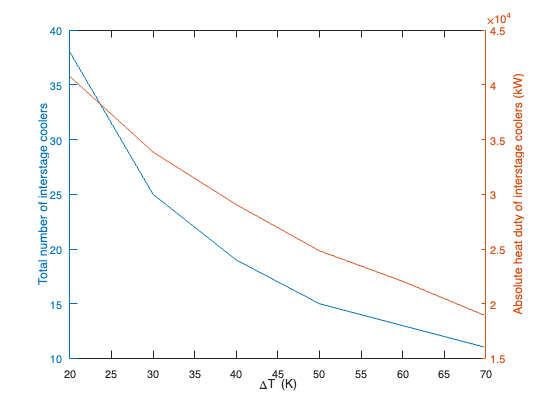


dutysum=double.empty(length(Tcool),0);
tot_duty=double.empty(length(Tcool),0);
    for i=1:length(Tcool)
        dutysum(i)= sum(duty(1:n_cooler(i,:)));%nparallel(i,1).*
        tot_duty(i)=nparallel(i).*dutysum(i);
    end
 ztotal=n_z;
 zavg=(z/(n_cooler+1));
 n_coolert = (n_cooler);
 n_reactort = nparallel.*((n_cooler)+1);

figure;
yyaxis left
plot(transpose(Tcool),n_coolert)
hold on
xlabel("\DeltaT (K)");
ylabel("Total number of interstage coolers")
yyaxis right
plot(transpose(Tcool),tot_duty);
hold off
ylabel("Absolute heat duty of interstage coolers (kW)")

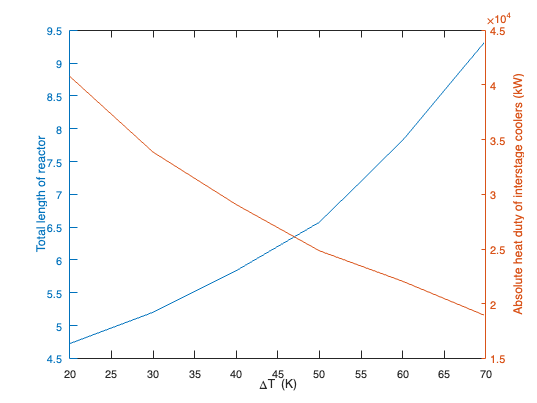


figure;
yyaxis left
plot(transpose(Tcool),ztotal)
hold on
xlabel("\DeltaT (K)")
ylabel("Total length of reactor")
yyaxis right
plot(transpose(Tcool),tot_duty)
hold off
ylabel("Absolute heat duty of interstage coolers (kW)")

function  [z1 mol1] = system_ode1(zrange, IC, isobaric, isothermal)
    [z1,mol1] = ode15s(@(z,mol) system_ode2(z,mol, isobaric, isothermal),zrange,IC);
  function systemode2= system_ode2(~,mol,isobaric,isothermal)
    %calling global variables
    global gc
    %FLowrate solution
    n_C2H4=mol(1);
    n_O2=mol(2);
    n_CO2=mol(3);
    n_C2H4O=mol(7);
    n_H20=mol(8);
    %setting isobaric isothermal non_isobaric and non_isothermal cases through if statments that can be
    %called through the function
    if isobaric==false
            P0=mol(9);
    else
            P0=IC(1,9);
    end
    if isothermal==false
            T=mol(10);
    else
            T=IC(1,10);
    end 
    %initial conditions
    n0_C2H4=IC(1);
    n0_O2=IC(2);
    n0_CO2=IC(3);
    n0_VC=IC(4);
    n0_inh=IC(5);
    n0_N2=IC(6);
    n0_C2H4O=IC(7);
    n0_H20=IC(8);
    % calulating toatl molar flow rate for initial and solutions
    n0_T=n0_C2H4+n0_O2+n0_CO2+n0_VC+n0_inh+n0_N2+n0_C2H4O+n0_H20;
    n_T=[n_C2H4 n_O2 n_CO2 n0_VC n0_inh n0_N2 n_C2H4O n_H20];
    n_Tsum= sum(n_T);
    % mole fractions
    y=n_T./n_Tsum;
    % compound partial pressures
    p=y.*P0;
    %K values
    K = exp(gc.Ea1+(gc.Ea2/(gc.Rg.*T)));
    %reaction rate equations
    R1=(1/3600).*(K(1).*p(1).*p(2))/(1+K(3).*p(2).^(1/2)+K(4).*p(2)+K(5).*p(1).*p(2).^(1/2)+K(6).*p(3)+K(7).*p(8)+K(8).*p(5)./p(4));
    R2=(1/3600).*(K(2).*p(1).*p(2))/((1+K(3).*p(2).^(1/2)+K(4).*p(2)+K(5).*p(1).*p(2).^(1/2)+K(6).*p(3)+K(7).*p(8)+K(8).*p(5)./p(4)).^2);
    %heat capactiy calculations
    Cp= (gc.a + gc.b*T + gc.c*T.^2 + gc.d*T.^3 + gc.e*T.^(-2));
    %output relevant Cp values
    Cp_C2H4= @(T) Cp(1);
    Cp_O2= @(T) Cp(2);
    Cp_CO2= @(T) Cp(3);
    Cp_N2= @(T) Cp(6);
    Cp_C2H4O= @(T) Cp(7);
    Cp_H20= @(T) Cp(8);
    %total heat capacity
    Cp_T = y(1).*Cp(1) + y(2).*Cp(2) + y(3).*Cp(3) + y(6).*Cp(6) + y(7).*Cp(7) + y(8).*Cp(8);%y(6)*Cp(6) +
    %Entalpies of reaction
    H_1=-105.12*1000;
    H_2=-705.575*1000;
    %chnage in enthalpy of reaction
    dH_R1= -integral(Cp_C2H4,298,T,"ArrayValued",true) - (1/2).*integral(Cp_O2,298,T,"ArrayValued",true) + H_1 + integral(Cp_C2H4O,298,T,"ArrayValued",true);
    dH_R2= -(1/2).*integral(Cp_C2H4,298,T,"ArrayValued",true) - (3/2)*integral(Cp_O2,298,T,"ArrayValued",true) + H_2 + integral(Cp_CO2,298,T,"ArrayValued",true) + integral(Cp_H20,298,T,"ArrayValued",true);
    %presure drop equation variables calculations
    G=(gc.m_T)/(1000*gc.A); %equation for superficial mass velocity
    v_T=(gc.Rg.*T)./(P0);%sum(gc.Mr.*n_T)./1000
    rho_g=sum(y.*gc.Mr)/(1000.*v_T);
    %setting odes to solve for the material and energy balances
    systemode2(1,1)= (-R1-(1/2).*R2).*(gc.A).*((1-gc.Void_frac).*gc.rho_cat);%output as (moles per second) per meter
    systemode2(2,1)= (-(1/2).*R1-(3/2).*R2).*(gc.A).*((1-gc.Void_frac).*gc.rho_cat);
    systemode2(3,1)= (R2).*(gc.A).*((1-gc.Void_frac).*gc.rho_cat);
    systemode2(4,1)=0;
    systemode2(5,1)=0;
    systemode2(6,1)=0;
    systemode2(7,1)= (R1).*(gc.A).*((1-gc.Void_frac).*gc.rho_cat);
    systemode2(8,1)= (R2).*(gc.A).*((1-gc.Void_frac).*gc.rho_cat);
    systemode2(9,1)=-(1.75*G^2*(1-gc.Void_frac))./(gc.D_p*rho_g*gc.Void_frac^3);%ode for non-isobaric reactor
    systemode2(10,1)= -((dH_R1*R1+dH_R2*R2)*gc.A.*(1-gc.Void_frac).*gc.rho_cat)./(Cp_T);%ode for non isobaric case
        if isothermal==true
            systemode2(10,1)= 0;%setting ode to 0 for isothermal case
        else
        end
        if isobaric == true
            systemode2(9,1) = 0;%setting ode to 0 for isobaric case
        else
        end
    end
end